# Chap 2. 이산 시간 신호 및 시스템

## 2.1 이산시간 신호

유한 신호(finite-duration) 행 벡터로 표현

n = [-3,-1,-1,0,1,2,3,4];
x = [2,1,0,2,4];

### 2.1.1 신호의 종류

1. 단위 샘플 신호

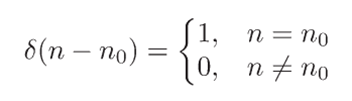

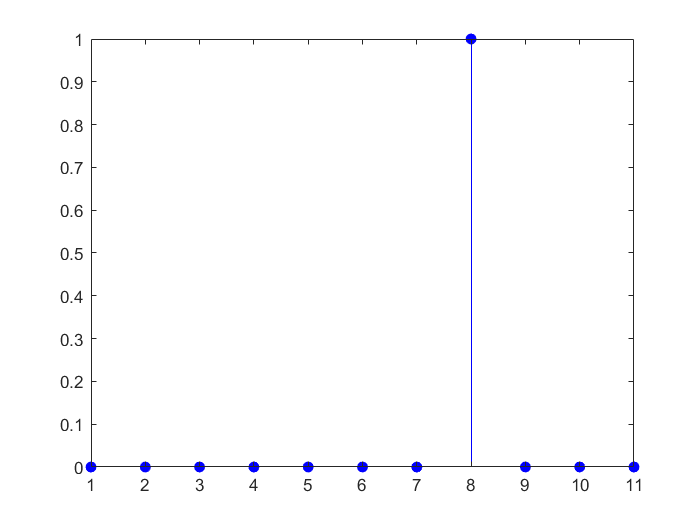

[x,n] = impseq(12,5,15);
n = 1:length(x);
figure()
stem(n,x,'b','filled');

2. 단위 계단 신호

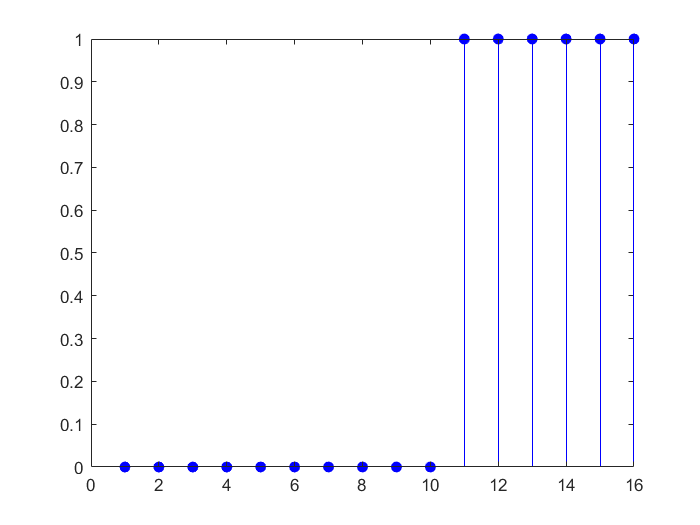

[x,n] = stepseq(15,5,20);
n = 1:length(x);
figure()
stem(n,x,'b','filled');

3. 실수 지수 신호

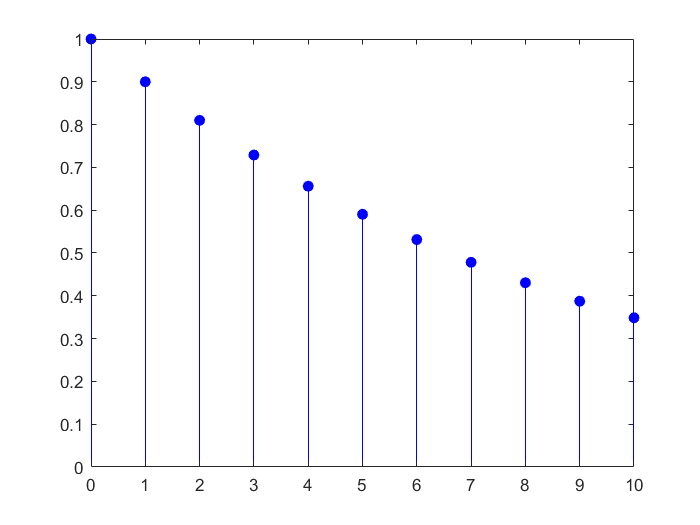

n = [0:10];
x = (0.9).^n;
figure()
stem(n,x,'b','filled');

4. 복소수 지수 신호

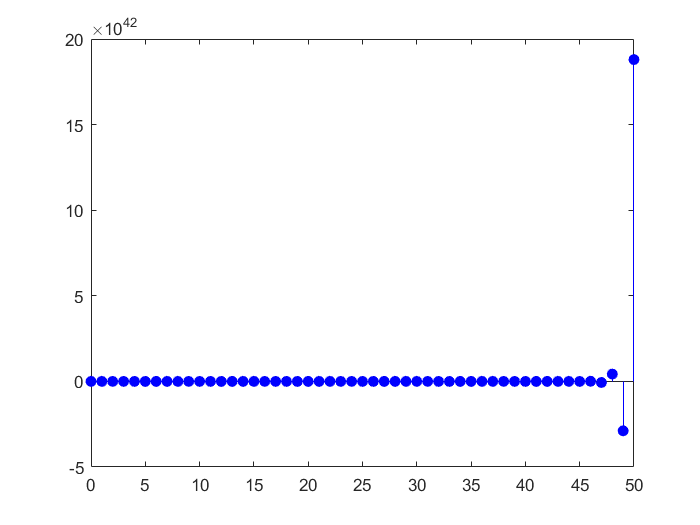

n = [0:50];
x = exp((2+3j)*n);
figure()
stem(n,x,'b','filled');

7. 주기 신호

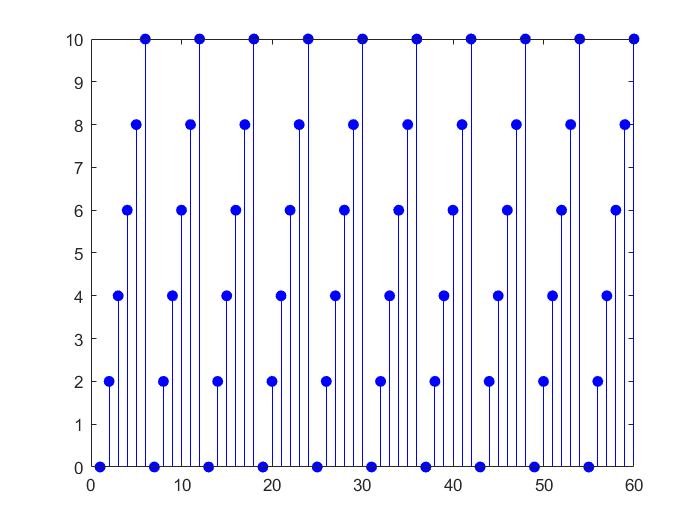

x = [0 2 4 6 8 10];
xtilde = x' * ones(1,10); 
xtilde = xtilde(:)'; % 행으로 만들어준다! + xtilde = 열벡터 하나로 쭉 만들어주는 기능을 한다!
n = 1:length(xtilde); 
stem(n,xtilde,'b','filled');

### 2.1.2 신호에 대한 연산

예제 2.1

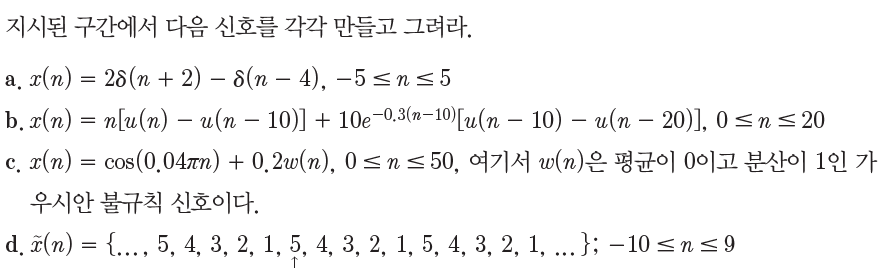

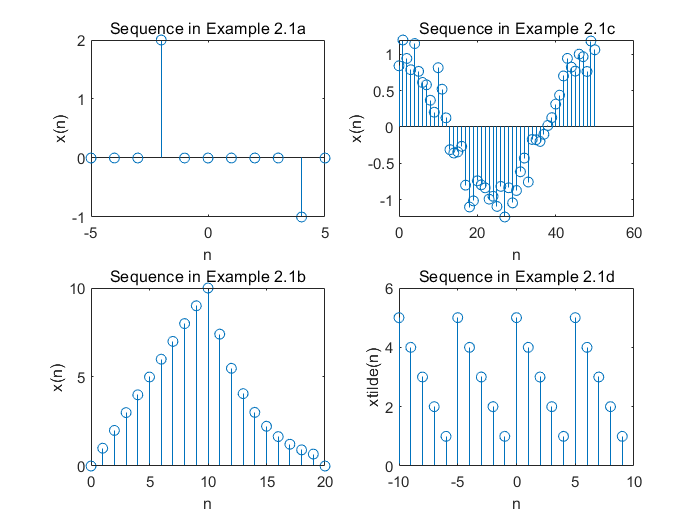

% 2.1a
n = [-5:5]; % 구간 지정
x = 2*impseq(-2,-5,5) - impseq(4,-5,5); %단위 신호 = impseq /// 정의한대로 진행을 해주는 것이다! 우린 정의한 함수를 쓰고 있는거임!
subplot(2,2,1); % 2 by 2  4분할 한다음 1번째에 그림을 그리겠다!
stem(n,x);
title('Sequence in Example 2.1a')
xlabel('n'); ylabel('x(n)');

% 2.1b
n = [0:20];
x1 = n.*(stepseq(0,0,20)-stepseq(10,0,20));
x2 = 10*exp(-0.3*(n-10)).*(stepseq(10,0,20)-stepseq(20,0,20));
x = x1 + x2;
subplot(2,2,3);
stem(n,x);
title('Sequence in Example 2.1b')
xlabel('n'); ylabel('x(n)');
% 2.1c
n = [0:50];
x = cos(0.04*pi*n) + 0.2*randn(size(n)); %size(n)은 크기를 알려준다! 1 51 이런식으로 행의 개수, 열의 개수를 출력해준다!
%randn = 평균이 0이고 분산이 1인 가우시안 불규칙 신호를 만들어줌! 고로 size(n)도 사용함!
subplot(2,2,2);
stem(n,x);
title('Sequence in Example 2.1c')
xlabel('n'); ylabel('x(n)');

% 2.1d
n = [-10:9];
x = [5,4,3,2,1];
xtilde = x' * ones(1,4);
xtilde = (xtilde(:))';
subplot(2,2,4);
stem(n,xtilde);
title('Sequence in Example 2.1d')
xlabel('n'); ylabel('xtilde(n)');

예제 2.2

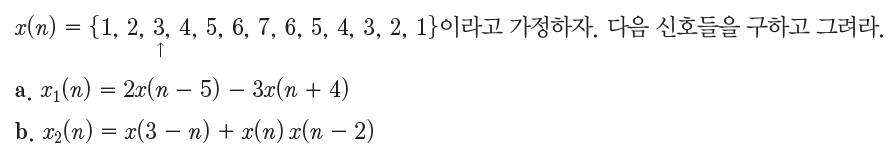

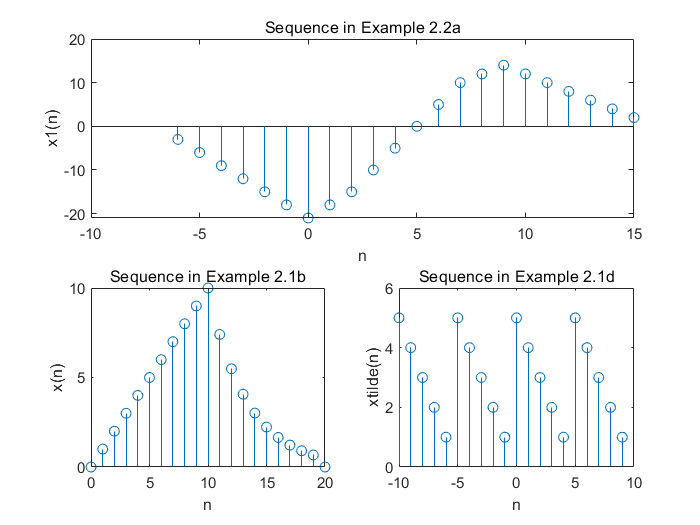

% n는 0일때 3인거지! 암튼 그런 식으로 잡아주면 된다!
n = -2:10;
x = [1:7, 6:-1:1];

% 예제 2.2a
[x11,n11] = sigshift(x,n,5);
[x12,n12] = sigshift(x,n,-4);
[x1,n1] = sigadd(2*x11, n11, -3*x12, n12);
subplot(2,1,1);
stem(n1,x1);
title('Sequence in Example 2.2a')
xlabel('n'); ylabel('x1(n)');

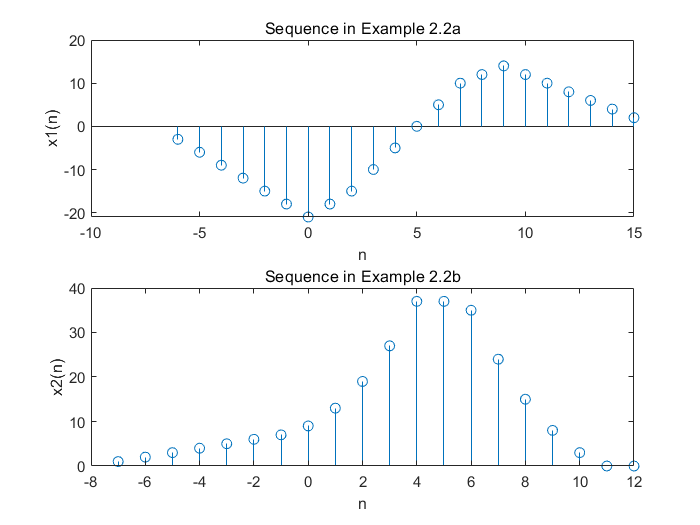


% 예제 2.2b
[x21,n21] = sigfold(x,n);
[x21,n21] = sigshift(x21,n21,3);
[x22,n22] = sigshift(x,n,2);
[x22,n22] = sigmult(x,n,x22,n22);
[x2,n2] = sigadd(x21,n21,x22,n22);
subplot(2,1,2); 
stem(n2,x2);
title('Sequence in Example 2.2b')
xlabel('n'); ylabel('x2(n)');

예제 2.3

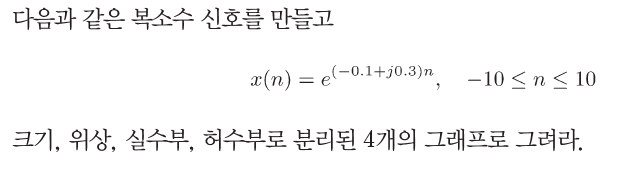

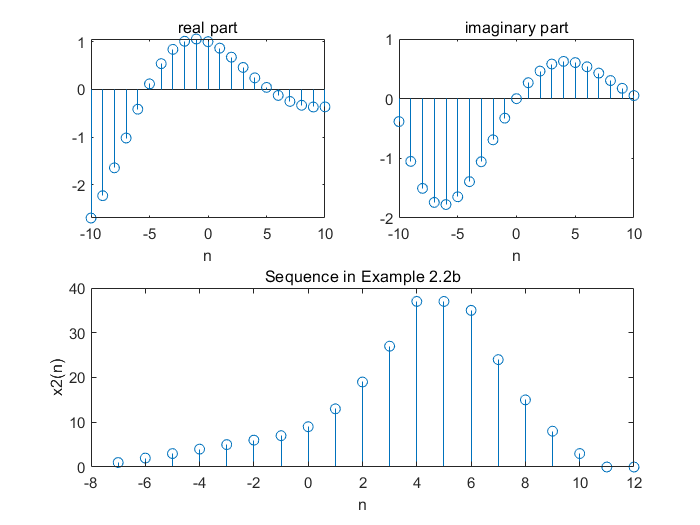

n = [-10:1:10];
alpha = -0.1+0.3j;
x = exp(alpha*n);
subplot(2,2,1); stem(n,real(x)); title('real part'); xlabel('n') % 실수부
subplot(2,2,2); stem(n,imag(x)); title('imaginary part'); xlabel('n') % 허수부

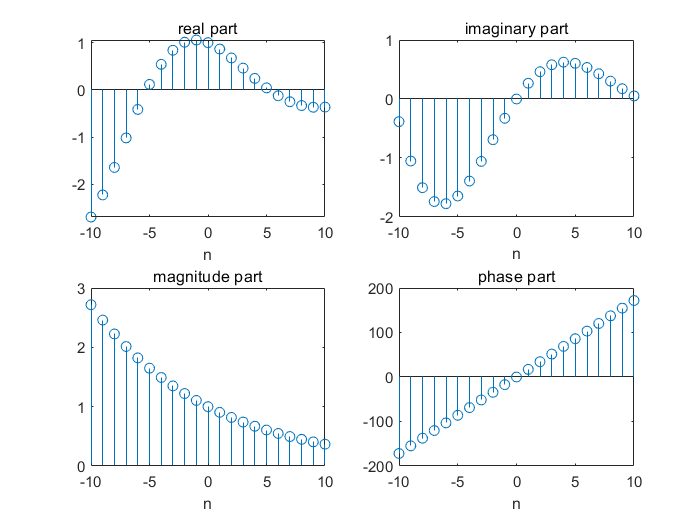

subplot(2,2,3); stem(n,abs(x)); title('magnitude part'); xlabel('n')
subplot(2,2,4); stem(n,(180/pi)*angle(x)); title('phase part'); xlabel('n')

### % 집에서 꼭 해보기!!!! 복습 의미로서!

### 예제

신호 s(t)에 잡음 n(t)가 섞인 신호는 x(t) = s(t) + a*n(t)와 같이 표현할 수 있다. 여기에서 잡음의 크기는 신호대 잡음비 (SNR)에 따라 다음과 같은 값을 갖는다. 

 
$$a=\frac{\frac{\sigma_s }{\sigma_n }}{{10}^{\frac{\mathrm{SNR}}{20}} }$$


이때 정현파 신호 s(t) = cos(2*pi*t)에 각각 균일분포 백색잡음과 정규분포 백색잡음이 섞인 경우의 파형을 그려라. 균일분포 백색잡음에 대한 SNR은 15[dB], 정규분포 백색잡음에 대한 SNR은 10[dB]이다. 그리고 각 경우에 대한 잡음의 크기 a를 구하라. 

% 코드 블럭을 생성할때 alt + enter 치면 된다!

1. 신호의 덧셈

function [y,n] = sigadd(x1,n1,x2,n2) %각 숫자에 해당하는 것이 시그널에 저장이 되어 있는거임!
    n = min(min(n1),min(n2)):max(max(n1),max(n2)); % 더한 신호의 총 길이를 재주는 것.  
    y1 = zeros(1,length(n)); 
    y2 = y1;
    y1(find((n>=min(n1))&(n<=max(n1))==1)) = x1; % find = 인덱스를 찾아주는 것. 0이 아닌 요소의 값이나 인덱스 찾기 -> 0 아닌것 찾기!
    y2(find((n>=min(n2))&(n<=max(n2))==1)) = x2; %두조건을 만족하는 것중 0이 아닌 것을 찾아라!
    y = y1 + y2;
end

2. 신호 곱셈

function [y,n] = sigmult(x1,n1,x2,n2)
    n = min(min(n1), min(n2)):max(max(n1),max(n2));
    y1 = zeros(1,length(n));
    y2 = y1;
    y1(find((n>=min(n1))&(n<=max(n1))==1)) = x1;
    y2(find((n>=min(n2))&(n<=max(n2))==1)) = x2;
    y = y1.*y2;
end

4. 자리이동 Shifting

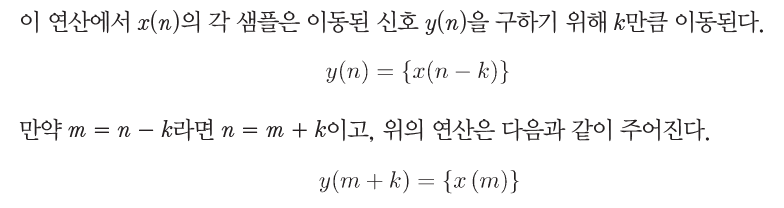

function [y,n] = sigshift(x,m,k)
    n = m+k; %단순히 k만큼 이동시켜주는 것!
    y = x;
end

5. 반전

function [y,n] = sigfold(x,n)
    y = fliplr(x); % flip이란 함수 - 요소의 순서를 뒤집어준다! fliplr 두번째 dimension 즉 열을 기준으로 flip을 하겠다!
    %도움말에서 검색해보면 아주 자세하게 나와있다!
    n = -fliplr(n);
end

function [x,n] = impseq(n0,n1,n2)
    n = [n1:n2];
    x = [(n-n0) == 0];
end

function [x,n] = stepseq(n0,n1,n2)
    n = [n1:n2];
    x = [(n-n0) >= 0];
end